# MSessionExplorer.SetColumn

Ignore code in this section

if exist('isRun', 'var') && isRun
    se = seRaw.Duplicate;
    se.isVerbose = false;
    D = designfilt('bandpassiir', ...
        'FilterOrder', 20, ...
        'PassbandFrequency1', 1, ...
        'PassbandFrequency2', 100, ...
        'StopbandAttenuation1', 80, ...
        'PassbandRipple', 0.1, ...
        'StopbandAttenuation2',80, ...
        'DesignMethod','ellip', ...
        'SampleRate', 1e3);
else
    edit MSessionExplorer.Examples.SetColumn
    return;
end

**Description**

help MSessionExplorer.SetColumn

  Add, update or delete column(s) in a data table
 
    SetColumn(tbName, colIDs, colData)
    SetColumn(tbName, colIDs, func, rowScope)
 
  Inputs
    tbName          The name of a table that contains the columns of interest. 
    colIDs          1) Column name(s) as a string or a cell array of strings. 
                    2) Integer or logical indices of column. 
    colData         Data to add or update. Use [] to delete. 
    func            A function handle that receives one input and gives one output. 
    rowScope        'each' or 'all'. 'each' applies func to each row separately, whereas 
                    'all' applies to all rows (concatenated) as one continuous series. 



**Example 1**

**Add a column to a table**

se.Preview('behavValue')

    trialNum    cue      posIndex      water    opto
    ________    ___    ____________    _____    ____

       1        100    [6×1 double]     100     NaN 
       2        100    [6×1 double]     100     NaN 
       3        100    [6×1 double]     100     NaN 
       4        100    [6×1 double]     100     NaN 
       5        100    [6×1 double]     100     NaN 
       6        100    [6×1 double]     100     NaN 




C = NaN(se.numEpochs, 1);

se.SetColumn('behavValue', 'optoPower', C);

se.Preview('behavValue')

    trialNum    cue      posIndex      water    opto    optoPower
    ________    ___    ____________    _____    ____    _________

       1        100    [6×1 double]     100     NaN        NaN   
       2        100    [6×1 double]     100     NaN        NaN   
       3        100    [6×1 double]     100     NaN        NaN   
       4        100    [6×1 double]     100     NaN        NaN   
       5        100    [6×1 double]     100     NaN        NaN   
       6        100    [6×1 double]     100     NaN        NaN   



**Example 2**

**Update specific columns in a table using table names**

se.Preview('behavValue')

    trialNum    cue      posIndex      water    opto    optoPower
    ________    ___    ____________    _____    ____    _________

       1        100    [6×1 double]     100     NaN        NaN   
       2        100    [6×1 double]     100     NaN        NaN   
       3        100    [6×1 double]     100     NaN        NaN   
       4        100    [6×1 double]     100     NaN        NaN   
       5        100    [6×1 double]     100     NaN        NaN   
       6        100    [6×1 double]     100     NaN        NaN   




C = zeros(se.numEpochs, 2);

se.SetColumn('behavValue', {'optoPower', 'opto'}, C);

se.Preview('behavValue')

    trialNum    cue      posIndex      water    opto    optoPower
    ________    ___    ____________    _____    ____    _________

       1        100    [6×1 double]     100      0          0    
       2        100    [6×1 double]     100      0          0    
       3        100    [6×1 double]     100      0          0    
       4        100    [6×1 double]     100      0          0    
       5        100    [6×1 double]     100      0          0    
       6        100    [6×1 double]     100      0          0    



**Update specific columns in a table using integer indices**

C = ones(se.numEpochs, 2);

se.SetColumn('behavValue', [5 6], C);

se.Preview('behavValue')

    trialNum    cue      posIndex      water    opto    optoPower
    ________    ___    ____________    _____    ____    _________

       1        100    [6×1 double]     100      1          1    
       2        100    [6×1 double]     100      1          1    
       3        100    [6×1 double]     100      1          1    
       4        100    [6×1 double]     100      1          1    
       5        100    [6×1 double]     100      1          1    
       6        100    [6×1 double]     100      1          1    



**Update specific columns in a table using logical indices**

C = rand(se.numEpochs, 2);

se.SetColumn('behavValue', logical([0 0 0 0 1 1]), C);

se.Preview('behavValue')

    trialNum    cue      posIndex      water     opto      optoPower
    ________    ___    ____________    _____    _______    _________

       1        100    [6×1 double]     100     0.54631    0.032336 
       2        100    [6×1 double]     100     0.63658     0.55707 
       3        100    [6×1 double]     100     0.57089      0.7198 
       4        100    [6×1 double]     100     0.92711     0.11041 
       5        100    [6×1 double]     100     0.86377     0.21665 
       6        100    [6×1 double]     100     0.16984     0.81102 



**Example 3**

**Remove specific columns in a table**

se.Preview('behavValue')

    trialNum    cue      posIndex      water     opto      optoPower
    ________    ___    ____________    _____    _______    _________

       1        100    [6×1 double]     100     0.54631    0.032336 
       2        100    [6×1 double]     100     0.63658     0.55707 
       3        100    [6×1 double]     100     0.57089      0.7198 
       4        100    [6×1 double]     100     0.92711     0.11041 
       5        100    [6×1 double]     100     0.86377     0.21665 
       6        100    [6×1 double]     100     0.16984     0.81102 




se.SetColumn('behavValue', {'optoPower', 'opto'}, []);

se.Preview('behavValue')

    trialNum    cue      posIndex      water
    ________    ___    ____________    _____

       1        100    [6×1 double]     100 
       2        100    [6×1 double]     100 
       3        100    [6×1 double]     100 
       4        100    [6×1 double]     100 
       5        100    [6×1 double]     100 
       6        100    [6×1 double]     100 



**Example 4**

**Apply user function to specific columns**

    Filter time series data in a few lines of code (visualization requires additonal lines)

Show the original time series

se.Preview('adc')

          time             lickportV           lickportH             tubeV               tubeH      
    ________________    ________________    ________________    ________________    ________________

    [13335×1 double]    [13335×1 single]    [13335×1 single]    [13335×1 single]    [13335×1 single]
    [11649×1 double]    [11649×1 single]    [11649×1 single]    [11649×1 single]    [11649×1 single]
    [14438×1 double]    [14438×1 single]    [14438×1 single]    [14438×1 single]    [14438×1 single]
    [ 8697×1 double]    [ 8697×1 single]    [ 8697×1 single]    [ 8697×1 single]    [ 8697×1 single]
    [ 9555×1 double]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]
    [ 9555×1 double]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]



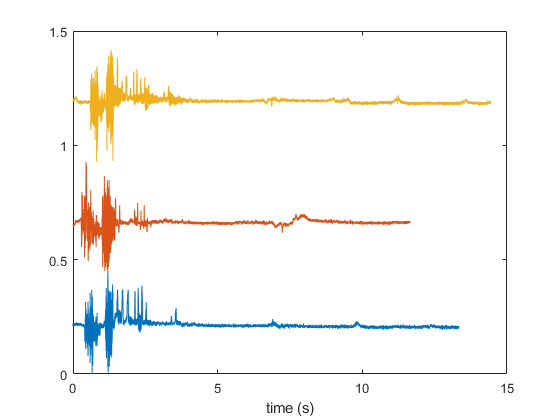


adc = se1.GetTable('adc');
MPlot.PlotTraceLadder(adc.time(1:3), adc.lickportV(1:3));
xlabel('time (s)');

Make an anonymous function that performs a bandpass filtering on input x (converted to double) and gives one output

filterFunc = @(x) filtfilt(D, double(x));


Apply filterFunc to each epoch independently using option 'each'. Note that the filtering artifacts at the start and end of each epoch. 

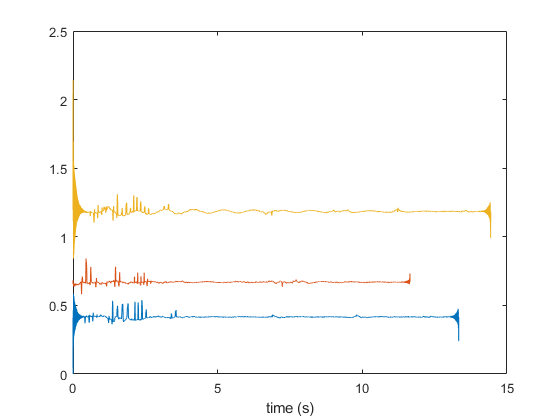

seCopy = se.Duplicate; % let's work on a copy

seCopy.SetColumn('adc', {'lickportV', 'lickportH'}, filterFunc, 'each');

adc = seCopy.GetTable('adc');
MPlot.PlotTraceLadder(adc.time(1:3), adc.lickportV(1:3));
xlabel('time (s)');

Apply filterFunc to all epochs after being concatenated using option 'all'. Note that the filtering artifacts is limited to the start of the first epoch (blue trace) and the end of the last epoch (not shown). 

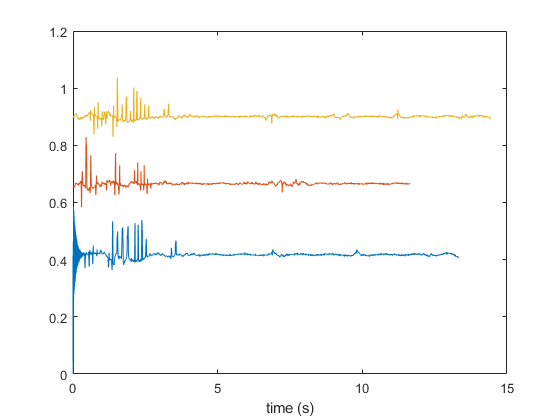

seCopy = se.Duplicate; % let's work on a copy

seCopy.SetColumn('adc', {'lickportV', 'lickportH'}, filterFunc, 'all');

adc = seCopy.GetTable('adc');
MPlot.PlotTraceLadder(adc.time(1:3), adc.lickportV(1:3));
xlabel('time (s)');